% Limpia la memoria y limpia la pantalla de operaciones anteriores
clc; clear; close all;

% Solicitar la cantidad de puntos
num_puntos = input('Ingrese la cantidad de puntos: ');

% Inicializar vectores para almacenar coordenadas X e Y
coordenadas_X = zeros(1, num_puntos);
coordenadas_Y = zeros(1, num_puntos);

% Solicitar las coordenadas X e Y para cada punto
for i = 1:num_puntos
    fprintf('Ingrese las coordenadas del punto %d:\n', i);
    coordenadas_X(i) = input('Coordenada X: ');
    coordenadas_Y(i) = input('Coordenada Y: ');
end

Ingrese las coordenadas del punto 1:
Ingrese las coordenadas del punto 2:
Ingrese las coordenadas del punto 3:
Ingrese las coordenadas del punto 4:
Ingrese las coordenadas del punto 5:
Ingrese las coordenadas del punto 6:
Ingrese las coordenadas del punto 7:



% Cerrar el polígono repitiendo el primer punto al final
coordenadas_X(end+1) = coordenadas_X(1);
coordenadas_Y(end+1) = coordenadas_Y(1);

% Calcular el área utilizando la fórmula del polígono (método 1)
area_total = 0;
for i = 1:num_puntos
    area_total = area_total + (coordenadas_X(i) * coordenadas_Y(i+1) - coordenadas_X(i+1) * coordenadas_Y(i));
end
area_total = abs(area_total) / 2;

% Calcular los azimuts y rumbos
azimuts = zeros(1, num_puntos);
rumbos = strings(1, num_puntos);

% Calcular los azimuts y rumbos
for i = 1:num_puntos
    dx = coordenadas_X(i+1) - coordenadas_X(i);
    dy = coordenadas_Y(i+1) - coordenadas_Y(i);
    
    % Calcular el azimut 
    azimut = atan2d(dy, dx); % atan2d: Función para calcular el angulo en grados
    if azimut < 0
        azimut = azimut + 360;
    end
    azimuts(i) = azimut;
    
    % Calcular el rumbo
    angulo = mod(azimut, 360);
    if angulo >= 0 && angulo < 90
        cuadrante = 'NE';
        rumbo = angulo;
    elseif angulo >= 90 && angulo < 180
        cuadrante = 'SE';
        rumbo = 180 - angulo;
    elseif angulo >= 180 && angulo < 270
        cuadrante = 'SW';
        rumbo = angulo - 180;
    else
        cuadrante = 'NW';
        rumbo = 360 - angulo;
    end
    rumbos(i) = sprintf('%.2f° %s', rumbo, cuadrante);
end

% Mostrar resultados del primer metodo
fprintf('\nÁrea total (método 1): %.2f unidades cuadradas\n', area_total);


Área total (método 1): 6029.92 unidades cuadradas


fprintf('\nAzimuts y Rumbos entre puntos:\n');


Azimuts y Rumbos entre puntos:


for i = 1:num_puntos
    fprintf('Del punto %d al punto %d: Azimut = %.2f°, Rumbo = %s\n', ...
        i, mod(i,num_puntos)+1, azimuts(i), rumbos(i));
end

Del punto 1 al punto 2: Azimut = 121.27°, Rumbo = 58.73° SE
Del punto 2 al punto 3: Azimut = 73.62°, Rumbo = 73.62° NE
Del punto 3 al punto 4: Azimut = 23.17°, Rumbo = 23.17° NE
Del punto 4 al punto 5: Azimut = 291.07°, Rumbo = 68.93° NW
Del punto 5 al punto 6: Azimut = 244.39°, Rumbo = 64.39° SW
Del punto 6 al punto 7: Azimut = 208.66°, Rumbo = 28.66° SW
Del punto 7 al punto 1: Azimut = 0.00°, Rumbo = 0.00° NE


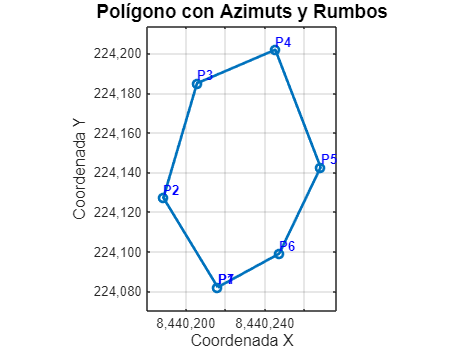


% Método Gráfico - Método Cerrado
figure;
plot(coordenadas_X, coordenadas_Y, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
title('Polígono con Azimuts y Rumbos', 'FontSize', 14);
xlabel('Coordenada X', 'FontSize', 12);
ylabel('Coordenada Y', 'FontSize', 12);
axis equal;

% Se ajustan los margenes dependiendo de la magnitud de las coordenadas utilizadas
marginX = (max(coordenadas_X) - min(coordenadas_X)) * 0.1;
marginY = (max(coordenadas_Y) - min(coordenadas_Y)) * 0.1;
xlim([min(coordenadas_X) - marginX, max(coordenadas_X) + marginX]);
ylim([min(coordenadas_Y) - marginY, max(coordenadas_Y) + marginY]);

% Ajuste del texto en la grafica
for i = 1:num_puntos
    text(coordenadas_X(i), coordenadas_Y(i), ...
        sprintf('P%d', i), ...
        'FontSize', 10, 'Color', 'blue', 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

% Se dibuja el eje "X" y "Y", si estos cruzan en el origen (0,0)
if min(coordenadas_X) < 0 && max(coordenadas_X) > 0
    xline(0, '--k', 'LineWidth', 1);
end
if min(coordenadas_Y) < 0 && max(coordenadas_Y) > 0
    yline(0, '--k', 'LineWidth', 1);
end

% Mejorar la estetica de los ejes del grafico
ax = gca;
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;
ax.XAxis.TickLabelFormat = '%,.0f';
ax.YAxis.TickLabelFormat = '%,.0f';


% Método Numérico 
% Método de Gauss
area_gauss = 0;
for i = 1:num_puntos
    area_gauss = area_gauss + (coordenadas_X(i) * coordenadas_Y(i+1) - coordenadas_X(i+1) * coordenadas_Y(i));
end
area_gauss = abs(area_gauss) / 2;

% Mostrar área calculada por Gauss
fprintf('\nÁrea calculada por el Método de Gauss: %.2f unidades cuadradas\n', area_gauss);


Área calculada por el Método de Gauss: 6029.92 unidades cuadradas



% Cálculo de Errores

% Calcular error relativo porcentual de cada método respecto al área de Gauss
error_total = abs(area_total - area_gauss) / area_gauss * 100;
error_gauss = abs(area_gauss - area_gauss) / area_gauss * 100; % será 0, pues es el mismo valor

% Mostrar errores
fprintf('Error del método 1 (area_total): %.4f%%\n', error_total);

Error del método 1 (area_total): 0.0000%


fprintf('Error del Método de Gauss (area_gauss): %.4f%%\n', error_gauss);

Error del Método de Gauss (area_gauss): 0.0000%
